# Coordinate Systems

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

A coordinate system imposes a geometric structure on a space, allowing points to be identified by a set of numbers, called coordinates. The choice of a coordinate system impacts what shapes are easy to locate, describe, or track in that space. 

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## History of Coordinate Systems

The earliest origins of coordinate systems involve locating points on the earth or in the sky as part of what we now call geography, astronomy, or cartography. This led to a coordinate system of latitude and longitude lines on the earth and many engineering challenges to build accurate clocks and other geolocation systems. 

The concept of coordinate systems, which connects algebraic and geometric ideas in an abstract space, is credited to René Descartes in the early 1600s; however, others also explored these concepts. The first abstract coordinate system is the Cartesian coordinate system, which has mutually perpendicular straight axes that intersect at a single point, which is called the origin.

## Standard Coordinate Systems

## Two Dimensions

### Cartesian Coordinates

In two dimensions, the Cartesian coordinate axes are usually called the $x$-axis and the $y$-axis. In three dimensions, we add a $z$-axis. Each point in space is represented by an ordered pair $(x,y)$ in 2D or triple $(x,y,z)$ in 3D of values corresponding to the distance from the origin one must travel along the corresponding direction from the origin, $(0,0)$, to reach the point.

  **Try**. Investigate the representation of a point in 2D Cartesian coordinates.

x = 2;  y =  -4;
Animate = true;    

Plot2DPoint([x y],ShowCoordinates=Animate)

 **Exercise 1.** Use the button to generate and display a random point. Then, identify the point shown in standard Cartesian coordinates `(x,y)`. 

 
pt = randi([-6 6],[1 2]);
Plot2DPoint(pt,ShowCoordinates=false,ShowOrigin=false,AddTitle=false)
title("What are the coordinates of the point?")

mySoln = "";   
if mySoln == ""
    disp("Please enter a point.")
else
    ParseAndGiveFeedback(mySoln,pt)
end

### Polar Coordinates

The most natural coordinates to describe 2D space are sometimes based on circles. This is called a **polar coordinate** **system**, and the coordinates are $(r,\theta)$, where $r$ is the distance from the origin and $\theta$ is the azimuthal angle measured counterclockwise from the $+x$-axis. 

Polar coordinates make it easy to represent figures with angular components, such as a fan. The first line plots $r = \frac{0.15\theta}{2\pi}$, and the others are evenly-spaced angular shifts of the first spoke. Think about what shape you expect and then plot the function.

theta = linspace(0,2*pi,50);
r = linspace(0,0.3,50);
NumSpokes = 6; 
SpokeShift = linspace(0,2*pi,NumSpokes+1);
thetaWheel = theta + SpokeShift(1:end-1)';
polarplot(thetaWheel,r)

####  **Application: Orienteering**

Orienteering is an outdoor adventure sport that combines running with navigation. Participants use a map and compass to navigate through diverse and often unfamiliar terrain, aiming to visit a series of checkpoints, known as controls, in the correct order and as quickly as possible. The challenge lies in choosing the most efficient route between controls while accurately navigating the landscape.

Polar coordinates are relevant in orienteering when using a compass to determine direction. In polar coordinates, a position is described by a distance from a reference point and an angle from a reference direction. Orienteers use the compass to measure the angle or bearing from their current location to the next control point. The bearing is typically measured in degrees from magnetic north, corresponding to the angle in polar coordinates. By combining this directional information with distance estimates from the map, orienteers can plot a course and make precise navigational decisions to reach their checkpoints efficiently.

## Three Dimensions

### Cartesian Coordinates

In three dimensions, we add a $z$-axis to the $x$-axis and $y$-axis of 2D Cartesian coordinates. Each point in space is represented by an ordered triple $(x,y,z)$ of values corresponding to the distance from the origin, $(0,0,0)$. One must travel the given distance along the corresponding direction from the origin to reach the point.

  **Try**. Explore these plots of surfaces in three-dimensional space. 

[x,y,z,label] =DefineCubePoints;

function label = DefineDefault
label = "default";
end

function [x,y,z,label] = DefineSpherePoints(radius)
arguments
    radius (1,1) double = 1
end

% Define the sphere parameters
[r,n] = deal(radius,50); % radius and number of points

% Create a grid of points on the sphere
[phi,theta] = meshgrid(linspace(0,2*pi,n),linspace(0,pi,n));
x = r * sin(theta) .* cos(phi);
y = r * sin(theta) .* sin(phi);
z = r * cos(theta);
label = "Sphere";
end

function [x,y,z,label] = DefineCubePoints
sidelength = 0.8;
n = 50;
EdgePoints = linspace(0,sidelength,n);
[face1,face2] = meshgrid(EdgePoints,EdgePoints);
spacer = nan([1,n]);
x = [face1;spacer;face1;spacer;face2;spacer;face2;spacer;zeros(n);spacer;sidelength*ones(n)]; % bottom, top, left, right, front, back
y = [face2;spacer;face2;spacer;zeros(n);spacer;sidelength*ones(n);spacer;face1;spacer;face1];
z = [zeros(n);spacer;sidelength*ones(n);spacer;face1;spacer;face1;spacer;face2;spacer;face2];
label = "Cube";
end

function [x,y,z,label] = DefineRibbonPoints
width = 0.3;
n = 50;
rVals = linspace(width,2*width,n);
thetaVals = linspace(0,4*pi,n);
[r,theta] = meshgrid(rVals,thetaVals);
zVals = linspace(-0.3,0.6,n);
x = r.*cos(theta);
y = r.*sin(theta);
z = ones(size(x)).*zVals';
label = "Ribbon";
end

% Plot the selected surface
OpenInWindow = false; % open in popup window

IsDefault = label=="default";

if ~IsDefault
    if OpenInWindow
        OpenPopup
    end

    s = surf(x,y,z,FaceAlpha=0.5,EdgeColor="none");
    axis equal;
    if label == "Cube"
        % Scale the axis limits
        s.Parent.XLim = s.Parent.XLim*1.1;
        s.Parent.YLim = s.Parent.YLim*1.1;
        s.Parent.ZLim = s.Parent.ZLim*1.1;
    end
    xlabel("x-axis");
    ylabel("y-axis");
    zlabel("z-axis");
    title(label + " in Cartesian Coordinates");
    if OpenInWindow
        subtitle("Use the 'Return to script' button when you are done")
    end
    grid on;
else
    clear IsDefault
    disp("This is the default value. Please make a selection to continue.")
end

 **Reflect.** How would you describe these surfaces in words? Are you thinking about everyday objects or algebraic or geometric terms?  

 **Exercise 2.** Which of the following algebraic formulas describes the surface you selected?

a) $\{(x,y,z)~|~0\leq x,y \leq 0.8, \text{ and } z=0 ~\text{ or }~ z=0.8\}$ 

     and $\left\{(x,y,z)~|~0\leq x,z \leq 0.8 \text{ and } y=0 ~\text{ or }~ y=0.8\right\}$ 

     and $\{(x,y,z)~|~0\leq y,z \leq 0.8, \text{ and } x=0 ~\text{ or }~ x=0.8\}$

b) $\left\{(x,y,z)~|~x^2+y^2+z^2 = 1\right\}$

c) $\left\{(x,y,z)~|~0.3 \leq \sqrt{x^2+y^2} \leq 0.6 ~\text{ and }~ 0 \leq \arctan\left(\frac{y}{x}\right) \leq 4\pi ~\text{ and } -0.3 \leq z \leq 0.6\right\}$

choice = "??";
if exist("label","var") && label ~= "default"
    CheckExercise2(choice,label)
else
    warning("You must select a surface before completing this Exercise.")
end

### Spherical Coordinates

A spherical coordinate system defines a point in three-dimensional space with three values: the radial distance from a central point, the polar angle  (also called the inclination) from a reference direction, and the azimuthal angle in a reference plane. While academic disciplines use different conventions for spherical coordinates, they mostly agree that one coordinate tracks the distance from the origin. We'll call this distance $\rho$ (`rho)`. Therefore, we can plot a sphere of radius $3$ in spherical coordinates by noting that it is the set of all points in spherical coordinates where $\rho = 3$. The other two coordinates are angles generally denoted as $\theta$ (`theta`) and $\phi$ (`phi`). In mathematics, $\theta$ is the azimuthal angle in the $xy$-plane measured counterclockwise from the $+x$-axis, and $\phi$ is the polar angle measured from the $+z$-axis. This means that $0\leq \rho < \infty$, $0\leq \theta <2\pi$, and $0\leq \phi \leq \pi$, and the points are written as $(\rho,\theta,\phi)$. 

This expression of spherical coordinates is one way of smoothly extending the idea of polar coordinates into three dimensions. Note that for values in the $xy$-plane, the first two components in spherical coordinates are exactly the same as the representation in polar coordinates.

% Plot a point in spherical coordinates

% Define the arrow parameters
rho = 1; % length of the arrow
theta_arrow = pi/4; % angle from the positive x-axis in the x-y plane
phi_arrow = pi/4; % angle from the positive z-axis
ShowComponents = false; OpenInWindow = false; % open in popup window
 
ValidInputs = true;

if ShowComponents && rho==0
    warning("This plot collapses to the origin when rho=0.")
end

% Check spherical sanity
if rho < 0
    warning("This is an improper value for rho. Remember that rho is a distance, rho >= 0.")
    ValidInputs = false;
end
if 0 > theta_arrow || 2*pi <= theta_arrow
    warning("This is an improper value for theta. Remember that 0 <= theta < 2*pi.")
    ValidInputs = false;
end
if 0 > phi_arrow || phi_arrow > pi
    warning("This is an improper value for phi. Remember that 0 <= phi <= pi.")
    ValidInputs = false;
end


if OpenInWindow
    OpenPopup
end

if ValidInputs
    % Calculate the arrow endpoint in Cartesian coordinates
    x_arrow = rho * sin(phi_arrow) * cos(theta_arrow);
    y_arrow = rho * sin(phi_arrow) * sin(theta_arrow);
    z_arrow = rho * cos(phi_arrow);

    q = scatter3(x_arrow,y_arrow,z_arrow,80,"filled",SeriesIndex=4);
    xlabel("x-axis")
    ylabel("y-axis")
    zlabel("z-axis")

    if rho~=0
        q.Parent.XLim = [-rho rho];
        q.Parent.YLim = [-rho rho];
        q.Parent.ZLim = [-rho rho];
        all_max = 1.1*rho;
    else
        LimPt = 0.1;
        all_max = 1.1*LimPt;
        % q.Parent.XLim = [-LimPt LimPt];
        % q.Parent.YLim = [-LimPt LimPt];
        % q.Parent.ZLim = [-LimPt LimPt];
    end

    if ShowComponents
        hold on
        % Plot the arrow from the origin to the point
        quiver3(0,0,0,x_arrow,y_arrow,z_arrow,"off",LineWidth=3,MaxHeadSize=0.2,SeriesIndex=3);
        quiver3(0,0,0,all_max,0,0,LineWidth=2,MaxHeadSize=0,SeriesIndex=2);
        text(0.95*all_max,0,0,'+x',FontSize=12,HorizontalAlignment="center",SeriesIndex=2)
        quiver3(0,0,0,0,0,all_max,LineWidth=2,MaxHeadSize=0,SeriesIndex=1);
        text(0,0,0.95*all_max,'+z',FontSize=12,HorizontalAlignment="center",SeriesIndex=1)
        quiver3(0,0,0,x_arrow,y_arrow,0,"off",LineWidth=2,MaxHeadSize=0,SeriesIndex="none",LineStyle=":")
        thetaAnglePoints = linspace(0,theta_arrow,50);
        phiAnglePoints = linspace(0,phi_arrow,50);
        plot3(0.1*all_max*cos(thetaAnglePoints),0.1*all_max*sin(thetaAnglePoints),zeros(size(thetaAnglePoints)),SeriesIndex="none");
        plot3(0.3*rho*cos(theta_arrow).*sin(phiAnglePoints),0.3*rho*sin(theta_arrow).*sin(phiAnglePoints),0.3*rho*cos(phiAnglePoints),SeriesIndex=4)
        % Add xy-plane
        [xPlanePts,yPlanePts]  = meshgrid([-rho rho],[-rho rho]);
        s=surf(xPlanePts,yPlanePts,zeros(2),FaceAlpha=0.2);
        % Add rho-sphere
        [xSph,ySph,zSph,~] = DefineSpherePoints(rho);
        surf(xSph,ySph,zSph,FaceAlpha=0.2,EdgeColor="none")
        hold off

        % Add labels for the arrow
        text(1.05*x_arrow,1.05*y_arrow,1.05*z_arrow,sprintf('\\rho = %.2f',rho), ...
            FontSize=12,HorizontalAlignment="left",SeriesIndex=3);
        text(0.3*rho*sin(phi_arrow/2)*cos(theta_arrow),0.3*rho*sin(phi_arrow/2)*sin(theta_arrow),0.3*rho*cos(phi_arrow/2),sprintf('\\phi = %.2f',phi_arrow),...
            FontSize=12,HorizontalAlignment="right",SeriesIndex=4);
        text(0.15*all_max*cos(theta_arrow/2),0.15*all_max*sin(theta_arrow/2),0,sprintf('\\theta = %.2f',theta_arrow),...
            FontSize=12,HorizontalAlignment="left",SeriesIndex="none");
        axis square
        box off
    end

end

  **Pro-tip**. Click the figure and use the Rotate 3D ([image: Rotate 3D toolbar icon]) tool to move the plot around to see the different components. 

 **Practical Note:** In fact, while $\rho < 0$ does not make sense, it can be appropriate to describe space in spherical coordinates using any real values as angles $\theta$ and $\phi$. That said, describing any point using the limited range presented above is always possible. For instance, the point $\left(1,\frac{10\pi}{3},\frac{\pi}{3}\right)$ is the same point as $\left(1,\frac{4\pi}{3},\frac{\pi}{3}\right)$. Or $\left(2,\frac{\pi}{3},\frac{3\pi}{2}\right)$ is the same point as $\left(2,\frac{4\pi}{3},\frac{\pi}{2}\right)$.

 **Cautionary Note:** The physics conventions for spherical coordinates are $(r,\theta,\phi)$, where $r$ is the distance from the origin, $\theta$ is the polar angle from the positive $z$-axis to the radial line, and $\phi$ is the angle of rotation around the $z$-axis measured from the positive $x$-axis. A third convention in navigation and engineering uses radial distance, azimuthal angle, and elevation measured in a range of $\left[\frac{-\pi}{2},\frac{\pi}{2}\right]$ with respect to the $xy$-plane. The navigation convention will frequently measure the angles in degrees with the azimuthal angle, or longitude, between -180$^{\circ}$ and 180$^{\circ}$ and the elevation angle, or latitude, between -90$^{\circ}$ and 90$^{\circ}$. 

**In any situation where you encounter spherical coordinates, first make sure you know what convention the author is using.**

#### **Application: Tracking Satellites**

Spherical coordinates are essential in planning and describing the motion of satellites around the Earth because they provide a natural way to represent positions in a three-dimensional space centered on the Earth. This system is advantageous because it aligns well with the Earth's curvature and rotational symmetry, allowing for straightforward calculations of orbital paths, velocities, and positions relative to the Earth's surface. By using spherical coordinates, engineers and scientists can efficiently model satellite orbits, determine their coverage areas, and plan maneuvers with respect to the Earth's geometry. One such application is described in a [satellite tracking documentation example](https://www.mathworks.com/help/fusion/ug/detect-and-track-a-LEO-satellite-constellation-with-ground-radars.html). 

### Cylindrical Coordinates

Cylindrical coordinates extend polar coordinates into three dimensions by including a height value measured above or below the polar coordinate plane: $(r,\theta,z)$. This lets us plot elegantly curvy shapes and surfaces, and volumes with rotational symmetry. Consider the following:


$$r(z) = \text{max}\left(0.02,a+b\sin\left(\frac{\pi z}{h}\right)-\cos\left(\frac{6\pi z}{h}\right)\right)$$



$$r(\theta) = a-b\cos\left(h\theta\right)$$
 


$$r(\theta,z) = z\left(\cos\left(\frac{\theta}{h}\right)\right)^2-a\sin\left(\frac{b\theta}{h}\right)$$
 

  **Try**. Play around with different values of $a$, $b$, $h$ and the maximum and minimum values of $z$. How different do the shapes look?

z = linspace(0,2,100); % Create a vector for z from 0 to 3
theta = linspace(0,2*pi,100); % Create a vector for theta from 0 to 2*pi
[Z,Theta] = meshgrid(z,theta); % Create a meshgrid for z and theta
a = 1; b = 3; h = 10;
R = max(0.02,a+b*sin(pi*Z/h)-(cos(6*pi*Z/h)).^2); OpenInWindow = false; % open in popup window
 
X = R.*cos(Theta);
Y = R.*sin(Theta);
if OpenInWindow
    OpenPopup
end
surf(X,Y,Z,LineWidth=0.1,EdgeAlpha=0.4); % Plot the surface
xlabel("x-axis"); % Label x-axis
ylabel("y-axis"); % Label y-axis
zlabel("z-axis"); % Label z-axis

####  **Application: Radar Tracking Systems**

Consider the problem of [tracking an aircraft](https://www.mathworks.com/help/fusion/ug/simulate-and-track-en-route-air-traffic-with-earth-centered-scenarios.html) along its flight path. A radar station can determine the azimuthal angle to the aircraft and how far away it is. The plane's GPS can broadcast its measured location, and all of this data can be combined into a cylindrical coordinate system with the origin at the radar station to be able to plot the location of the plane on a map with polar coordinates, but also to track the altitude, especially as the plane comes in to land. 

####  **Application: Rotationally Symmetric and Extruded Solids**

When designing objects for manufacturing, it is common to create a computer-aided design (or CAD) model of the object. A standard approach to building a CAD model is to combine simpler shapes to build the representation. But what shapes count as simple? That depends on the coordinate system being used! 

Cylindrical coordinates can be used to create various useful shapes through rotational symmetry and extrusion. A cog, for instance, 

 
z = [0 0.5];
theta = linspace(0,2*pi,640); % Create a vector for theta from 0 to 2*pi
% [Z,Theta] = meshgrid(z,theta); % Create a meshgrid for z and theta

R = 3;
A = 0.3;
r = R + A*sign(cos(8*theta));
polarplot(theta,r,SeriesIndex=2,LineWidth=2)
hold on
polarplot(theta,0.5*ones(size(theta)),SeriesIndex=3,LineWidth=2)
radiusregion(0,0.5,SeriesIndex="none",FaceAlpha=1)
radiusregion(0.5,R-A,SeriesIndex=1,FaceAlpha=1)
OnPts = -pi/16:pi/4:2*pi;
OffPts = OnPts+ pi/8;
RadiusVec = ones(size(OnPts));
polarregion([OnPts;OffPts],[(R-A)*RadiusVec;(R+A)*RadiusVec],SeriesIndex=1,FaceAlpha=1)
hold off
legend(["$r = 3+0.3\text{sign}(\cos(8\theta))$" "r=0.5"],Interpreter="latex")

can be extruded up to the relevant height by simply including a range of acceptable $z$-values.

Alternatively, one can start with a 2D cross-section. 

 
function [zPath,rPath] = DefineCrossSection
z = 0:0.04:5;
r = 1+sin(z*pi/10);                % Main outer curve
r(1:5) = 1.3-2*(z(1:5)).^2;        % Add foot
r(end-7:end) = 2.2-z(1:8).^2;      % Add lip
rInner = 1.9*(fliplr(z)/5).^(1/3); % Inner curve

rPath = [r rInner r(1)];
zPath = [z fliplr(z) 0];
end
[zPath,rPath] = DefineCrossSection;
plot(rPath,zPath)
title("Cross-sectional slice")

Rotating this cross-section around the $z$-axis, we can build a 3D object.

OpenInWindow = false; % open in popup window
 
if OpenInWindow
    OpenPopup
else
    fig = figure;
end
theta = linspace(0,2*pi,50);
if ~exist("zPath","var") || ~exist("rPath","var")
    [zPath,rPath] = DefineCrossSection;
end
[Z,Theta] = meshgrid(zPath,theta); % Create a meshgrid for z and theta
[R,~] = meshgrid(rPath,theta);
surf(R.*cos(Theta),R.*sin(Theta),Z)
title("Solid of Rotation")
view([235.83 5.56])

You can explore these ideas in the [Multibody Simulation Onramp](https://matlabacademy.mathworks.com/details/multibody-simulation-onramp/ormb).

#### **Application: Modeling Microphones**

Spherical coordinates are used in microphone arrays to focus on sounds from specific directions. This helps microphones capture sound more precisely by placing them on a sphere. The system can enhance desired sounds and reduce noise by analyzing sound differences at each microphone.

Spherical harmonics are mathematical tools used to design microphones for  3D audio capture and noise-canceling systems by improving sound quality and directionality. Polar coordinates are helpful for cylindrical microphones like cardioid and shotgun types. Cardioid microphones pick up sound mainly from the front, reducing background noise. Shotgun microphones are even more focused, capturing sound from a specific area and minimizing ambient noise, making them ideal for film and TV production. You can see visualizations of [microphone response patterns](https://www.mathworks.com/help/phased/ug/introduction-to-hybrid-beamforming.html) in three dimensions in a discussion of hybrid beamforming or sliced 2D versions in an [introduction to beamforming](https://www.mathworks.com/help/phased/ug/introduction-to-differential-beamforming.html) to get an idea of how these coordinate systems help design microphones that effectively control sound direction and quality.

## Identifying Appropriate Coordinate Systems

In applying the concepts of coordinate systems, one of the challenges is deciding which coordinate system to use for what types of work. The geometric object is always the same, but the algebraic representation can look quite different in different coordinate systems and be more or less amenable to different types of computations. For the moment, let's consider some typical forms that are well-described by each coordinate system.

 **Exercise 3.** For each of the following problems, click the "Show shape" button to plot a shape, then choose the most straightforward coordinate system for plotting the shape depicted.

a)

 
% Plot a cardioid
Exercise3aShape = true;
theta = linspace(0,2*pi,200);
r = 0.3+cos(theta);
p = polarplot(theta,r,LineWidth=2);
grid off
axis off

aSoln = "default";
if exist("Exercise3aShape","var")
    CheckExercise3(aSoln,"a")
else
    disp("You must plot the shape before you can answer.")
end

b)

 
% Plot a cylinder of radius 1 and height 2
Exercise3bShape = true;
theta = linspace(0,2*pi,200);
r = 1;
z = linspace(-1,1,15);
[Z,Theta] = meshgrid(z,theta);
X = r*cos(Theta);
Y = r*sin(Theta);
s = surf(X,Y,Z,CData=zeros(size(Z)),EdgeColor="none");
hold on
fill3(X,Y,ones(size(Z)),0)
fill3(X,Y,-1*ones(size(Z)),0)
hold off
grid off
axis equal off

bSoln = "default";
if exist("Exercise3bShape","var")
    CheckExercise3(bSoln,"b")
else
    disp("You must plot the shape before you can answer.")
end

c)

 
% Plot the plane 2*x - 3*y = z
Exercise3cShape = true;
[x,y] = meshgrid(-2:0.1:2,-2:0.1:2); % Create a grid for x and y
z = 2*x - 3*y; % Calculate z based on the plane equation
surf(x,y,z,EdgeColor="none"); % Plot the surface
grid off
axis off

cSoln = "default";
if exist("Exercise3cShape","var")
    CheckExercise3(cSoln,"c")
else
    disp("You must plot the shape before you can answer.")
end

d) 

 
% Plot an ellipsoid with major radius 4 and minor radius 1
Exercise3dShape = true;
a = 4; % Major radius
b = 1; % Minor radius
[theta,phi] = meshgrid(linspace(0,2*pi,100),linspace(0,pi,100)); % Create a meshgrid for spherical coordinates

% Parametric equations for the ellipsoid
X = a * sin(phi) .* cos(theta);
Y = a * sin(phi) .* sin(theta);
Z = b * cos(phi);

% Plot the ellipsoid
figure;
surf(X,Y,Z,EdgeAlpha=0.4); % Plot the surface of the ellipsoid
grid off; % Turn on the grid
axis equal off; % Set equal scaling for all axes

dSoln = "default";
if exist("Exercise3dShape","var")
    CheckExercise3(dSoln,"d")
else
    disp("You must plot the shape before you can answer.")
end

## Conversion Between Coordinate Systems

Recall the relationships within a right triangle:

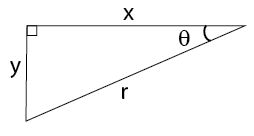


$$\frac{y}{x} = \tan\left(\theta\right)~~\Rightarrow~~\arctan\left(\frac{y}{x}\right) = \theta$$


and

$\sqrt{x^2+y^2} = r$.

Extending this relationship beyond the first quadrant we can handle values from $-\frac{\pi}{2}$ up to $\frac{\pi}{2}$ for $\theta$. Beyond that, we can use the periodicity of the tangent function to extend to the entire plane.

 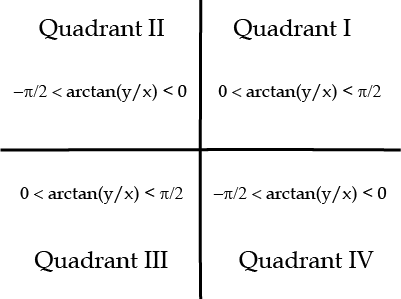

These values mean we must shift our computed $\theta$ values by various multiples of $\pi$ to shift the computed arctangent into the proper quadrant.

In the table below, $k = \begin{cases} 0 & x\geq 0,~y\geq 0 \\ 1 & x< 0 \\ 2 & x >0, ~ y < 0 \end{cases}$. 

This shift can also be described by quadrant. No shift is required in the first quadrant, but to keep the values of $\theta \in [0,2\pi)$, we have to shift by $\pi$ in quadrants II and III and by $2\pi$ in quadrant IV. Similar considerations with $\phi$ show that a shift of the arctangent is also needed to agree with the conventions agreed to above, shifting the range from $\left[\frac{-\pi}{2}, \frac{\pi}{2}\right]$ to $[0,\pi]$ and changing the direction to measure downwards from the $+z$-axis in the math and physics conventions rather than elevation above/below the $xy$-plane.  

 **Exercise 4.**  Choose a convention and generate a problem. 

Convention = "math";
 
[startPt,startCoords,endCoords] = CreateExercise4(6,Convention);

 You can use numbers, `pi`, `sqrt()`, and the trigonometric functions `sin()`, cos(), `atan()`, `sind()`, `cosd()`, and `atand()` in expressing your solution.

 **Practical Note:** The checking code on this exercise is looking for a precise answer. If you round your solution too much, your answer will not be accepted. 

  **Pro-tip**. The functions `sin()`, cos(), and `atan()` compute with angles in radians while  `sind()`, `cosd()`, and `atand()` compute with angles in degrees.

solnPt = "(x,y,z)"; 

if exist("startCoords","var") && exist("endCoords","var")
    numPt = PullOutPoint(solnPt,endCoords,Convention);
    out = CheckExercise4(numPt,startPt,startCoords,endCoords,Convention);
else
    warning("You must generate a problem before solving it.")
end

## Further Exploration: Plotting on a Spherical Surface

There are many other ways to represent space. Following the historical roots of identifying geographic locations, you can explore [geographic plots](https://www.mathworks.com/help/matlab/geographic-plots.html) where the coordinates are latitude (the number of degrees north or south of the equator) and longitude (the number of degrees east or west of the prime meridian). This connects to all sorts of interesting geometric questions because the curvature of the Earth means that your basic intuition about what it means to be a straight line, for instance, may need to be rethought.

  **Pro-tip**. MATLAB® offers different ways to visualize geographic data, from the standard visualization options available in MATLAB to more specialized options in the Mapping Toolbox™. The following example requires the Mapping Toolbox.

figure
load coastlines coastlat coastlon
latlim = [-85 85];
lonlim = [-180 180];
abm = worldmap(latlim,lonlim);
geoshow(coastlat,coastlon)

Identify a location, perhaps a city, by its latitude and longitude locations:

city1lat = 42.28; city1lon = -71.35;
% city1lat = 42.28; city1lon = -71.35; % Natick, MA, US

And a second one:

city2lat = 48.86; city2lon = 2.35;
% city2lat = 48.86; city2lon = 2.35; % Paris
% city2lat = -68; city2lon = 91; % On Antarctica
% city2lat = -77.07; city2lon = 167.31;  % McMurdo Station
 
scatterm(abm,[city1lat city2lat],[city1lon city2lon],50,"filled","pentagram",SeriesIndex=2)
% scatterm(city2lat,city2lon,50,"filled","pentagram",SeriesIndex=2)

### Great Circles and Rhumb Lines

One of the complexities of drawing flat maps of curved surfaces is that the [shortest distance](https://www.mathworks.com/help/map/rhumb-lines.html) will not appear as a straight line. These "shortest distance" lines are called geodesics. On a sphere, they are also called great circles. A rhumb line on a sphere has a constant slope. How do the great circle and rhumb line paths between your points compare?

 
figure
[latgc,longc] = track2(city1lat,city1lon,city2lat,city2lon);
[latrh,lonrh] = track2("rh",city1lat,city1lon,city2lat,city2lon);
gcDist = round(deg2km(distance(city1lat,city1lon,city2lat,city2lon)),1);
rhDist = round(deg2km(distance("rh",city1lat,city1lon,city2lat,city2lon)),1);

if city2lon-city1lon > 0 && lonrh(2)-lonrh(1) < 0
    idxgc = find(diff(longc)>320);
    idxrh = find(diff(lonrh)>320);
    % Handle the case where the longitude wraps around
    if ~isempty(idxgc)
        latgc = [latgc(1:idxgc); latgc(idxgc:end)];
        longc = [longc(1:idxgc); nan; longc(idxgc+1:end)];
    end
    if ~isempty(idxrh)
        latrh = [latrh(1:idxrh); latrh(idxrh:end)];
        lonrh = [lonrh(1:idxrh); nan; lonrh(idxrh+1:end)];
    end
end
mapChoice = "satellite";
geobasemap(mapChoice);
p = geoplot(latgc,longc,SeriesIndex=1,LineWidth=2);

hold on
geoplot(latrh,lonrh,SeriesIndex=2,LineWidth=2)
geoscatter(city1lat,city1lon,"pentagram","filled",SeriesIndex=3,MarkerEdgeColor="flat")
geoscatter(city2lat,city2lon,"pentagram","filled",SeriesIndex=3,MarkerEdgeColor="flat")
if (city2lat-city1lat)*(city2lon-city1lon) > 0
    dirString = "left";
else
    dirString = "right";
end

if mapChoice == "grayterrain" || mapChoice == "satellite"
    txtColor = "white";
else
    txtColor = "black";
end

text(latgc(33),longc(33),string(gcDist) + " km",HorizontalAlignment=dirString,Color=txtColor)
text(latrh(67),lonrh(67),string(rhDist) + " km",HorizontalAlignment=dirString,Color=txtColor)
hold off

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline** using the icon   at the top right of the Live Editor pane.

function Plot2DPoint(pt,opts)
arguments
    pt (1,2) double
    opts.ShowOrigin = true
    opts.ShowCoordinates = true
    opts.AddTitle = true
    opts.CoordinatesOnAxes (1,1) logical = false
end

figure

x = pt(1);
y = pt(2);

if opts.ShowOrigin
    hold on
    scatter(0,0,Marker="o",SizeData=50,LineWidth=2,SeriesIndex=2)
    hold off
end
if max(abs(x),abs(y)) <= 6
    n = 6;
    smLabels = -n:n;
else
    n = ceil(max(abs(x),abs(y)))+1;

    smallLabels = round(linspace(-n,n,10));
    smLabels = string.empty(2*n+1,0);

    for idx = 10:-1:1
        smLabels(n+1+smallLabels(idx)) = smallLabels(idx);
    end
end

if opts.ShowOrigin
    hold on
    scatter(x,y,"filled",Marker="o",SizeData=50,SeriesIndex=1)
    hold off
else
    scatter(x,y,"filled",Marker="o",SizeData=50,SeriesIndex=1)
end

ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
xlim([-n,n])
xticks(-n:n)
xticklabels(smLabels)
ylim([-n,n])
yticks(-n:n)
yticklabels(smLabels)
axis square
grid on



if opts.AddTitle
    title("$x = $"+x + " and $y = $" + y,Interpreter="latex")
end

if opts.ShowCoordinates
    if opts.CoordinatesOnAxes
        hold on
        plot([0 x],[0 0],LineWidth=2,SeriesIndex=3)
        plot([0 0],[0 y],LineWidth=2,SeriesIndex=4)
        plot([x x 0],[0 y y],":",SeriesIndex="none")
        hold off
        if x ~= 0
            text(x/2,y,string(x))
        end
        if y ~= 0
            text(x,y/2,string(y))
        end
        legend(["Origin" "$(x,y)$" "$x$-component" "$y$-component"],Interpreter="latex",Location="bestoutside");
    else
        hold on
        plotX = plot([0 0],[0 0],LineWidth=2,SeriesIndex=3);
        hold off
        ell = legend(["Origin" "$(x,y)$" "$x$-component"],Interpreter="latex",Location="bestoutside");

        t = linspace(0,abs(x)+abs(y),101);
        clear plotY
        for tIdx = 2:101
            if t(tIdx) <= abs(x)
                plotX.XData(2) = sign(x)*t(tIdx);
                pause(0.05)
            elseif t(tIdx) > abs(x)
                if ~exist("plotY","var")
                    hold on
                    plotY = plot([x x],[0 0],LineWidth=2,SeriesIndex=4);
                    hold off
                    ell.String{end} = "$y$-component";
                end
                plotY.YData(2) = sign(y)*(t(tIdx)-abs(x));
                pause(0.05)
            end
        end
    end
end

end

function ParseAndGiveFeedback(mySoln,pt)
arguments
    mySoln (1,1) string
    pt (1,2) double
end

signedNumPat = optionalPattern(whitespacePattern)+optionalPattern("-");

SolnPattern = "("+signedNumPat+digitsPattern(1)+optionalPattern(whitespacePattern)+","+...
    signedNumPat+digitsPattern(1)+optionalPattern(whitespacePattern)+ ")";

if ~contains(mySoln,SolnPattern)
    warning("Please enter your solution in the form (x,y). Do not forget the parentheses!")
else
    myPt = extract(mySoln,SolnPattern);
    if size(myPt) ~= [1 1]
        warning("Please enter a single point, only!")
        return
    else
        x = double(extractBetween(myPt,"(",","));
        y = double(extractBetween(myPt,",",")"));
        myPoint = [x y];
    end
    if all(myPoint == pt,"all")
        disp("That is correct, the point is (" + x + "," + y + ").")
        Plot2DPoint(pt,CoordinatesOnAxes=true,AddTitle=false)
    elseif myPoint(1) == pt(1)
        disp("Your x value is correct, but your y value is not." + newline + "Please try again.")
    elseif myPoint(2) == pt(2)
        disp("Your y value is correct, but your x value is not." + newline + "Please try again.")
    elseif myPoint(2)==pt(1) && myPoint(1) == pt(2)
        disp("You appear to have mixed up your x and y coordinates." + newline + ...
            "Please recheck your point and try again.")
    else
        disp("No, that is not the point shown." + newline + ...
            "Please test your solution with the first plotting interaction" + newline + ...
            "and then try again.")
    end
end
end

function CheckExercise2(myAns,shape)
arguments
    myAns (1,1) string {mustBeMember(myAns,["??","a)" "b)" "c)"])}
    shape (1,1) string {mustBeMember(shape,["Sphere" "Cube" "Ribbon"])}
end

if myAns == "??"
    disp("This is the default value, please select a set of equations.")
    return
end

flag = 0;
switch shape
    case "Cube"
        if myAns == "a)"
            disp("That is correct." + newline + ...
                "One way to describe a cube with Cartesian coodinates is a)," + newline + ...
                "as a union of 6 square faces.")
            flag = 1;
        end
    case "Sphere"
        if myAns == "b)"
            disp("That is correct." + newline + ...
                "One way to describe a sphere with Cartesian coodinates is b)," + newline + ...
                "a set of points that are all a fixed distance from the origin.")
            flag = 1;
        end
    case "Ribbon"
        if myAns == "c)"
            disp("That is correct." + newline + ...
                "One way to describe a ribbon with Cartesian coodinates is c)," + newline + ...
                "a set of points that are defined by a range of distances to the" + newline + ...
                "origin, and a range of angles from the x-axis, and a range of heights.")
            flag = 1;
        end
end
if ~flag
    switch myAns
        case "a)"
            disp("No, the equations in a) describe the following:")
            [x,y,z,~] = DefineCubePoints;
        case "b)"
            disp("No, the equations in b) describe the following:")
            [x,y,z,~] = DefineSpherePoints;
        case "c)"
            disp("No, the equations in c) describe the following:")
            [x,y,z,~] = DefineRibbonPoints;
    end
    surf(x,y,z,EdgeColor="none")
    axis square
    disp("Please try again.")
else
    disp("These descriptions might encourage you to think about additonal ways to describe space.")
end
end

function CheckExercise3(mySoln,val)
arguments
    mySoln (1,1) string {mustBeMember(mySoln,["Cartesian" "Spherical" "Polar" "Cylindrical" "default"])}
    val (1,1) string {mustBeMember(val,["a" "b" "c" "d"])}
end
if mySoln == "default"
    disp("Please select an option.")
    return
end

dimWrong = "That is the wrong dimension." + newline + "Please try again.";
genWrong = "That is not the easiest solution.";
switch val
    case "a"
        if mySoln == "Polar"
            disp("That is correct. The polar equations for this figure are:")
            syms r theta
            displayFormula("r == 0.3+cos(theta)")
        elseif mySoln == "Cartesian"
            disp(genWrong + " In Cartesian coordinates this looks like:")
            syms x y
            displayFormula("x^2+y^2 = (0.3 + x/sqrt(x^2+y^2))^2")
            disp("Please try again.")
        else
            disp("That would work, but how many dimensions are required for this plot?" + newline + ...
                "Please try again.")
        end
    case "b"
        if mySoln == "Polar"
            disp(dimWrong)
        elseif mySoln == "Cylindrical"
            disp("This is a classic cylinder! In cylindrical coordinates, this is:")
            syms r z
            displayFormula(["r <= 1" '" and "' "-1 <= z" '" and "' "z<= 1"])
        else
            disp(genWrong)
        end
    case "c"
        if mySoln == "Polar"
            disp(dimWrong)
        elseif mySoln == "Spherical" || mySoln == "Cylindrical"
            disp(genWrong)
        else
            disp("This is a plane. It is easy to describe in Cartesian coordinates:")
            syms x y z
            displayFormula("z == 2*x-3*y")
        end
    case "d"
        if mySoln == "Polar"
            disp(dimWrong)
        elseif mySoln == "Spherical"
            disp("This is an ellipsoid. It is easy to describe in spherical coordinates:")
            syms x y z theta phi
            displayFormula(['"For  "' "theta" '" in [0, "' "2*pi" '") and "' "phi" '" in [0,"' "pi" '"],"'])
            displayFormula(["x == 4 * sin(phi) .* cos(theta)"; "y == 4 * sin(phi) .* sin(theta)"; ...
                "z == cos(phi)"])
        elseif mySoln == "Cartesian"
            disp("Fair, this is an ellipsoid so it is straightforward to describe as:")
            syms x y z
            displayFormula("x^2/16+y^2+z^2 = 1")
            disp("That said, to actually plot this figure, the equations become uglier:")
            displayFormula(['"For  "' "x" '" in [-4,4],"'])
            displayFormula(['"and for "' "y" '" between "' "-sqrt(1-x^2/16)" '" and "' "sqrt(1-x^2/16)" '","'])
            displayFormula(['"and for "' "z" '" between "' "-sqrt(1-x^2/16-y^2)" '" and "' "sqrt(1-x^2/16-y^2)" '"."'])
            disp("Can you find an easier representation to plot?")
        else
            disp(genWrong)
        end
end
end

function [startPt,startCoords,endCoords] = CreateExercise4(NumRange,convention)
arguments
    NumRange (1,1) double {mustBePositive,mustBeInteger}
    convention (1,1) string {mustBeMember(convention,["math" "navigation" "physics"])}
end

coords = ["Cartesian" "spherical" "polar" "cylindrical"];
idxFrom = randi(4,1);
idxTo = randi(3,1);
if idxTo >= idxFrom
    idxTo = idxTo+1;
end
startCoords = coords(idxFrom);
endCoords = coords(idxTo);
pts = randi([-NumRange NumRange],[1 5]);
switch startCoords
    case "Cartesian"
        x = pts(1);
        y = pts(2);
        if endCoords == "polar"
            z = 0;
        else
            z = pts(3);
        end
        startPt = [x y z];
    case "spherical"
        rho = abs(pts(1));
        theta = (12+pts(2)+pts(4))/6*pi;
        if abs(theta-2*pi)<1e-5
            theta = 0;
        end
        if endCoords == "polar"
            phi = pi/2;
        else
            phi = (6+pts(3))/12*pi;
        end
        startPt = ApplyConvention([rho theta phi],"math",convention);
    case "polar"
        r = abs(pts(1));
        theta = (12+pts(2)+pts(4))/6*pi;
        if abs(theta-2*pi)<1e-5
            theta = 0;
        end
        if convention == "navigation"
            theta = theta*180/pi;
        end
        startPt = [r theta];
    case "cylindrical"
        r = abs(pts(1));
        theta = (12+pts(2)+pts(4))/6*pi;
        if abs(theta-2*pi)<1e-5
            theta = 0;
        end
        if endCoords == "polar"
            z = 0;
        else
            z = pts(3);
        end
        if convention == "navigation"
            theta = theta*180/pi;
        end
        startPt = [r theta z];
end

num1 = startPt(1);
num2 = startPt(2);
if numel(startPt) > 2
    num3 = startPt(3);
end
switch startCoords
    case "Cartesian"
        syms x y z
        ptArray = ["x == num1"; "y == num2"; "z == num3"];
    case "polar"
        syms r theta
        ptArray = ["r == num1"; "theta == num2"];
    case "cylindrical"
        syms r theta z
        ptArray = ["r == num1"; "theta == num2"; "z == num3"];
    case "spherical"
        if convention == "navigation"
            syms r elevation
            sym azimuth ;
            ptArray = ["azimuth == num1"; "elevation == num2"; "r==num3"];
        else
            syms rho theta phi
            ptArray = ["rho == num1"; "theta == num2"; "phi == num3"];
        end
end
endingPhrase = "from " + startCoords + " to " + endCoords + " using " + convention + " conventions." + "Enter your answer as: ";

displayFormula('"Please convert the point"')
displayFormula(ptArray)
displayFormula(['"from "' "startCoords" '" to "' "endCoords" '" using "' "convention" '" conventions. Enter your answer as: "'])
switch endCoords
    case "Cartesian"
        syms x y z
        displayFormula(['"("' "x" '","' "y" '","' "z" '")."']);
    case "polar"
        syms r theta
        displayFormula(['"("' "r" '","' "theta" '")"']);
    case "cylindrical"
        syms r theta z
        displayFormula(['"("' "r" '","' "theta" '","' "z" '")"']);
    case "spherical"
        if convention == "navigation"
            syms r elevation
            sym azimuth ;
            displayFormula(['"("' "azimuth" '","' "elevation" '","' "r" '")"']);
        else
            syms rho theta phi
            displayFormula(['"("' "rho" '","' "theta" '","' "phi" '")"']);
        end
end
    if convention == "navigation"
        displayFormula('"Note: All angles are measured in degrees."');
    else
        displayFormula('"Note: All angles are measured in radians."');
    end

end

function outPt = ApplyConvention(inPt,startConvention,endConvention)
% inPt is in math coordinates (rho,theta,phi)
if startConvention == endConvention
    outPt = inPt;
    return
end

if startConvention == "math"
    rho = inPt(1);
    theta = inPt(2);
    phi = inPt(3);
elseif startConvention == "physics"
    rho = inPt(1);
    theta = inPt(3);
    phi = inPt(2);
elseif startConvention == "navigation"
    rho = inPt(3); % rho = r
    theta = inPt(1)*pi/180; % theta converted from degrees to radians
    phi = pi/2-inPt(2)*pi/180; % phi converted from degrees to radians
elseif startConvention == "matlab"
    rho = inPt(3);
    theta = inPt(1);
    phi = pi/2-inPt(2);
end
switch endConvention
    case "math"
        outPt = [rho theta phi];
    case "physics"
        outPt = [rho phi theta];
    case "navigation"
        if theta <= pi
            az = 180/pi*theta;
        else
            az = 180/pi*theta - 360;
        end
        el = 90-180/pi*phi;
        outPt = [az el rho];
    case "matlab"
        az = theta;
        el = pi/2-phi;
        outPt = [az el rho];
end
end

function numPt = PullOutPoint(solnPt,endCoords,convention)
arguments
    solnPt (1,1) string
    endCoords (1,1) string {mustBeMember(endCoords,["Cartesian" "spherical" "polar" "cylindrical"])}
    convention (1,1) string {mustBeMember(convention,["math" "navigation" "physics"])}
end
if solnPt=="(x,y,z)"
    disp("This is the default value, please enter your solution as numbers in the correct form.")
    numPt = nan;
    return
end

mathSymbols = asManyOfPattern(digitsPattern | characterListPattern("+-*/.,") | "pi"|whitespacePattern,1);
trigFunctionsPattern = asManyOfPattern(optionalPattern(mathSymbols) + asManyOfPattern("sin"|"cos"|"atan"|"sqrt"|"sind"|"cosd"|"atand")+"("+mathSymbols+")" + optionalPattern(mathSymbols));

if contains(solnPt,"(") && contains(solnPt,")")
    midStr = extractBetween(solnPt,textBoundary+"(",")"+textBoundary);
    if contains(midStr,"sin"|"cos"|"atan"|"sqrt")
        midStr = extract(midStr,trigFunctionsPattern);
    else
        midStr = extract(midStr,mathSymbols);
    end
    if any(midStr == "")
        warning("You must enter your point in standard mathematical notation." + newline + ...
            "You must use opening and closing parentheses and you may use" + newline + ...
            "numbers, +, - , *, /, sqrt(), sin(), cos(), atan(), sind(), cosd()," + newline + ...
            "atand(), and pi in your solutions. You may not use any other functions. ")
        numPt = nan;
        return
    end
    outStr = [];
    while contains(midStr,",")
        outStr = [outStr extractBefore(midStr,",")];
        midStr = extractAfter(midStr,",");
    end
    outStr = [outStr midStr];
    numPt = zeros(size(outStr));
    for idx = 1:length(outStr)
        numPt(idx) = ConvertToNumber(outStr(idx),idx,endCoords,convention);
    end
else
    warning("You must enter your point in standard mathematical notation." + newline + ...
        "You must use opening and closing parentheses and you may use" + newline + ...
        "numbers, sqrt(), sin(), cos(), atan(), sind(), cosd()," + newline + ...
        "atand(), and pi in your solutions. You may not use any other functions. ")
    numPt = nan;
end
end

function num = ConvertToNumber(str,coord,endCoords,convention)
arguments
    str (1,1) string
    coord (1,1) double {mustBePositive,mustBeInteger}
    endCoords (1,1) string {mustBeMember(endCoords,["Cartesian" "spherical" "polar" "cylindrical"])}
    convention (1,1) string {mustBeMember(convention,["math" "navigation" "physics"])}
end
num = double(str);
if isnan(num)
    num = eval(str);
end

if endCoords == "Cartesian"
elseif (endCoords == "polar" || endCoords == "cylindrical") && coord == 2
    if convention == "navigation"
        num = mod(num,360);
    else
        num = mod(num,2*pi);
    end
elseif endCoords == "spherical"
   switch convention
       case "navigation"
        switch coord
            case 1
                num = mod(num,360);
            % case 2
            %     num = mod(num,180);
        end
       case "math"
        switch coord
            case 2
                num = mod(num,2*pi);
            % case 3
            %     num = mod(num,pi);
        end
       case "physics"
                   switch coord
            case 2
                num = mod(num,2*pi);
            % case 3
            %     num = mod(num,pi);
                   end
   end
end
if abs(num) < 1e-15
    num = 0;
end
end

function tf = CatchImproperDimensions(vec,len)
tf = 0;
if numel(vec) ~= len
    warning("This vector is the wrong dimension.")
    tf = 1;
end
end

function endPt = CheckExercise4(solnPt,startPt,startCoords,endCoords,convention)
arguments
    solnPt
    startPt
    startCoords (1,1) string {mustBeMember(startCoords,["Cartesian" "spherical" "polar" "cylindrical"])}
    endCoords (1,1) string {mustBeMember(endCoords,["Cartesian" "spherical" "polar" "cylindrical"])}
    convention (1,1) string {mustBeMember(convention,["math" "navigation" "physics"])}
end
if isnan(solnPt)
    disp("Please try again.")
    endPt = nan;
    return
end
switch startCoords
    case "Cartesian"
        x = startPt(1);
        y = startPt(2);
        z = startPt(3);
    case "spherical"
        navPt = ApplyConvention(startPt,convention,"matlab");
        [x,y,z] = sph2cart(navPt(1),navPt(2),navPt(3));
    case "polar"
        if convention == "navigation"
            [x,y,z] = pol2cart(startPt(2)*pi/180,startPt(1),0);
        else
        [x,y,z] = pol2cart(startPt(2),startPt(1),0);
        end
    case "cylindrical"
        if convention == "navigation"
        [x,y,z] = pol2cart(startPt(2)*pi/180,startPt(1),startPt(3));
        else
            [x,y,z] = pol2cart(startPt(2),startPt(1),startPt(3));
        end
    otherwise
        warning("You shouldn't be here.")
end

switch endCoords
    case "Cartesian"
        if CatchImproperDimensions(solnPt,3)
            endPt = nan;
            return
        end
        endPt = [x y z];
        xVal = solnPt(1);
        yVal = solnPt(2);
        zVal = solnPt(3);
        syms x y z
        outStr = ["x == xVal"; "y == yVal"; "z == zVal"];

    case "spherical"
        if CatchImproperDimensions(solnPt,3)
            endPt = nan;
            return
        end
        [a,b,c] = cart2sph(x,y,z);
        endPt = ApplyConvention([a,b,c],"matlab",convention);
        if convention == "navigation"
            syms r elevation
            sym azimuth ;
            azVal = endPt(1);
            elVal = endPt(2);
            rVal = endPt(3);
            outStr = ["azimuth == azVal"; "elevation == elVal"; "r == rVal"];
        else
            rhoVal = endPt(1);
            thetaVal = endPt(2)/pi;
            phiVal = endPt(3)/pi;
            syms rho theta phi
            outStr = ["rho == rhoVal"; "theta == thetaVal*pi"; "phi == phiVal*pi"];
            if thetaVal == 0
                outStr(2) = "theta == 0";
            end
            if phiVal == 0
                outStr(3) = "phi == 0";
            end
        end

    case "polar"
        if CatchImproperDimensions(solnPt,2)
            endPt = nan;
            return
        end
        [a,b] = cart2pol(x,y);
        if convention == "navigation"
            a = mod(a*180/pi,360);
        else
            a = mod(a,2*pi);
        end
        endPt = [b a];
        rVal = solnPt(1);
        thetaVal = solnPt(2);
        syms r theta
        if convention ~= "navigation"
            thetaVal = thetaVal/pi;
            outStr = ["r == rVal"; "theta == thetaVal*pi"];
            if thetaVal == 0
                outStr(2) = "theta == 0";
            end
        else
            outStr = ["r == rVal"; "theta == thetaVal"];
        end

    case "cylindrical"
        if CatchImproperDimensions(solnPt,3)
            endPt = nan;
            return
        end
        [a,b,c] = cart2pol(x,y,z);
        if convention == "navigation"
            a = mod(a*180/pi,360);
        else
            a = mod(a,2*pi);
        end
        rVal = solnPt(1);
        thetaVal = solnPt(2);
        zVal = solnPt(3);
        endPt = [b a c];
        syms r theta z
        if convention ~= "navigation"
            thetaVal = thetaVal/pi;
            outStr = ["r == rVal"; "theta == thetaVal*pi"; "z == zVal"];
            if thetaVal == 0
                outStr(2) = "theta == 0";
            end
        else
            outStr = ["r == rVal"; "theta == thetaVal"; "z == zVal"];
        end

    otherwise
        warning("You shouldn't be here.")
end


if all(size(solnPt) == size(endPt))
    if norm(solnPt-endPt) < 1e-5
        disp("That looks good!")
        disp("This point can be written as:")
        displayFormula(outStr)
    elseif endCoords ~= "Cartesian" && endPt(1) == 0
        if solnPt(1) == 0
            disp("This is just the point at the origin.")
            disp("Any choice of angles will work, such as:")
            displayFormula(outStr)
        else
            disp("How far is this point from the origin?")
            disp("Please try again.")
        end
    else
        disp("Your calculations are off. Please try again.")
    end
else
    disp("Your dimensions are off. Please try again.")
end
end

function OpenPopup
fig = figure;
fp = matlab.desktop.editor.getActiveFilename;
fig.Visible = "on";
btn = uibutton(fig,"Text","Return to script","Position",[10 10 100 20],"ButtonPushedFcn",@(src,event)buttonCallback(fig,fp));

    function buttonCallback(fig,fp)
        edit(fp)
        close(fig);
    end
end